load('sub-DM1005_ses-intraop_task-smsl_ft-raw_filt_trial_ar-E_ref-CTAR_not-denoised.mat')

Loading the data we have D_trial_ref that has information about trials, times and labels. There are 144 trials in total which we can obtain from length(D_trial_ref.trial). Post this we can analyze any channel by simply calling D_trial_ref.trial{i} to access ith trial.To further acces a specific channel all we need to do is D_trial_ref{i}(m, :). That is the mth channel of the ith trial.

data_chan_1 = D_trial_ref.trial{1}(1,:)

data_chan_1 =    -9.1146   -6.5464    0.4895    6.5991   18.6310   33.6225   48.8394   57.4019   66.9745   68.4965   55.0811   41.5421   25.7027   12.2784   -1.2469   -5.6230   -9.5568  -13.9601  -11.3579   -6.3625    1.3301   14.6497   27.4510   38.1840   44.7602   49.9802   44.0526   32.6851   20.6375    5.5710   -4.9365  -15.6677  -22.1973  -33.3517  -40.3145  -33.1119  -25.3260  -15.6682   -0.8025   13.4238   21.9083   29.3792   33.4892   26.8927   19.8355   13.5108    9.9008    4.0918   -2.5052   -9.2187


data_chan_120 = D_trial_ref.trial{1}(120,:)

data_chan_120 =   -17.8712  -13.5390  -11.8376   -9.7679   -4.8037    1.3470    0.5519   -6.8044   -7.1515   -5.2684   -6.6053   -6.8759   -7.6824  -11.7598   -7.5457   -3.3803    2.8079   11.6179   19.2249   18.0445   18.9055   20.9507   24.9741   28.5029   34.4997   40.2106   37.9588   34.0773   35.3872   40.0570   44.7186   45.9353   45.0472   48.1226   48.1487   46.5276   36.3754   31.7537   29.3544   27.5671   29.7638   35.7723   39.0861   41.2068   41.3859   39.4770   32.9798   22.1818   14.8258    6.2709


After loading the data, we can obtain the number of time points for which it was recorded using the length(data_chan_1). Following this, we have to select window_size and number of overlapping points before obtaining the MSCOHERE value. There is an additional variable fs in the mix that is the sampling frequency which we can obtain from the data as D_trial_ref.fsample

fs = D_trial_ref.fsample

fs = 1000

time_points = length(data_chan_120)

time_points = 4925

window_size = 64

window_size = 64

noverlap = 32

noverlap = 32

Post this we calculate coherence using MSCOHERE. The function description is as follows:

`mscohere(`[`x`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-x)`,`[`y`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-x)`,`[`window`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-window)`)` uses `window` to divide `x` and `y` into segments and perform windowing.

`mscohere(`[`x`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-x)`,`[`y`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-x)`,`[`window`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-window)`,`[`noverlap`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-noverlap)`)` uses `noverlap` samples of overlap between adjoining segments.

`mscohere(`[`x`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-x)`,`[`y`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-x)`,`[`window`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-window)`,`[`noverlap`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-noverlap)`,`[`nfft`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-nfft)`)` uses `nfft` sampling points to calculate the discrete Fourier transform.

`[`[`cxy`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-cxy)`,`[`f`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-f)`] = mscohere(`[`x`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-x)`,`[`y`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-x)`,`[`window`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-window)`,`[`noverlap`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm-noverlap)`,`[`f`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm_sep_shared-f)`,`[`fs`](https://in.mathworks.com/help/signal/ref/mscohere.html#bvi4lxm_sep_shared-fs)`)` returns the magnitude-squared coherence estimate at the frequencies specified in `f`.

Here fs must be the sixth input to the mscohere function

So, we need to first define the frequencies at which we need the coheres

f = 1:0.1:250

f =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


Then we apply the mschohere

[cxy, f] = mscohere(data_chan_1,data_chan_120,window_size,noverlap,f,fs)

cxy =     0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0031    0.0031    0.0031    0.0031    0.0031    0.0030    0.0030    0.0030    0.0030    0.0030    0.0029    0.0029    0.0029    0.0029    0.0028    0.0028    0.0028    0.0028    0.0027    0.0027    0.0027    0.0027    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025


f =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


We can use this information to plot coherence vs frequency for the whole data

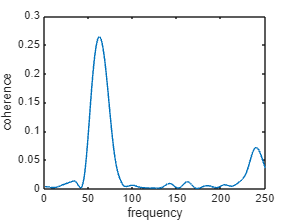

plot(f,cxy)
xlabel("frequency")
ylabel("coherence")

This is a good way to start analysing coherence. But we cannot analyse over time points using this. That is this is not a correct way to estimate for non stationary signals. And it would be better to wavelet coherence which is especially used for non-stationary signals

P.S. Pay attention to the cxy = mscohere function. If you give a window of size 1024. the number of points in cxy = 513 by default this is because of the property of FFT to get similar values on negtive and positive sides, so we divide it by two and increase by 1 to get the middle point. It is independent of number of samples as we average all the frames to get the coherence and hence not useful for non-stationary signals.

P.P.S If we assume the signal is semi-stationary, we can divide the signal into frames and calculate the same for each window.